**List of image filenames**

image_filenames = {
    'Fig0316(1)(top_left).tif', 'Fig0316(2)(2nd_from_top).tif', ...
    'Fig0316(3)(third_from_top).tif', 'Fig0316(4)(bottom_left).tif'};

**Histogram calculation**

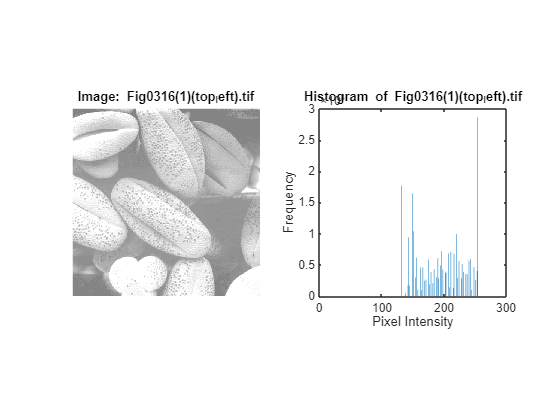

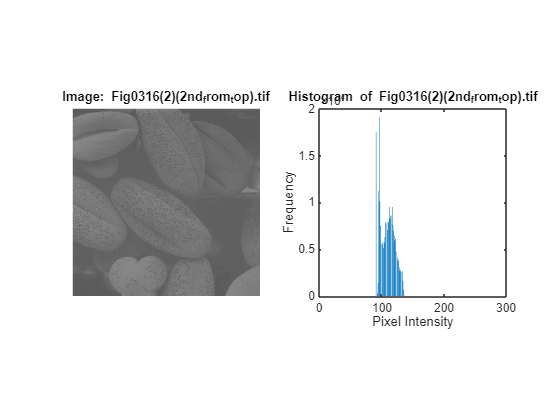

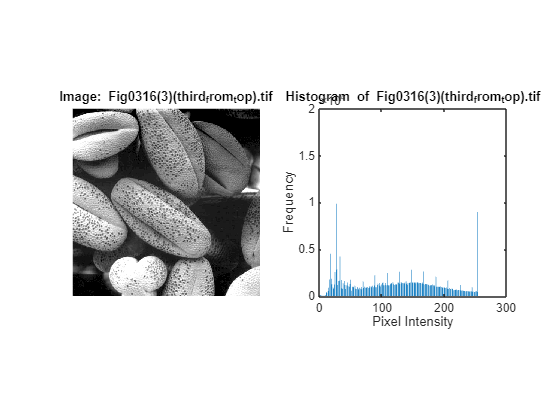

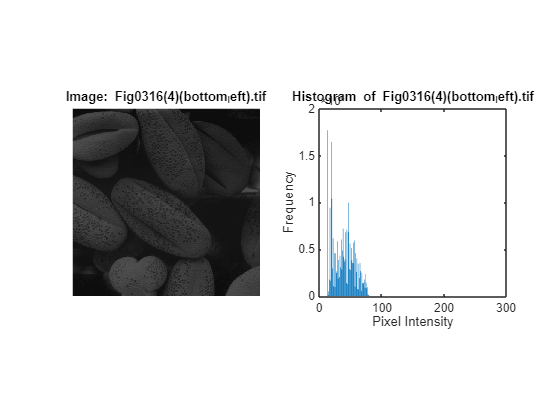

num_bins = 256;

for i = 1:length(image_filenames)
    img = imread(image_filenames{i});
    
    hist = zeros(1, num_bins);
    
    for row = 1:size(img, 1)
        for col = 1:size(img, 2)
            pixel_value = img(row, col);
            hist(pixel_value + 1) = hist(pixel_value + 1) + 1;
        end
    end
    
    figure;
    
    subplot(1, 2, 1);
    imshow(img);
    title(['Image: ', image_filenames{i}]);
    
    subplot(1, 2, 2);
    bar(0:num_bins-1, hist);
    title(['Histogram of ', image_filenames{i}]);
    xlabel('Pixel Intensity');
    ylabel('Frequency');
    
    axis square;
end